%% Parameters
N = 128;                  % matrix size (isotropic)
voxel_size = [0.5 0.5 0.5];     % mm
thr = 0.5;                % TKD threshold

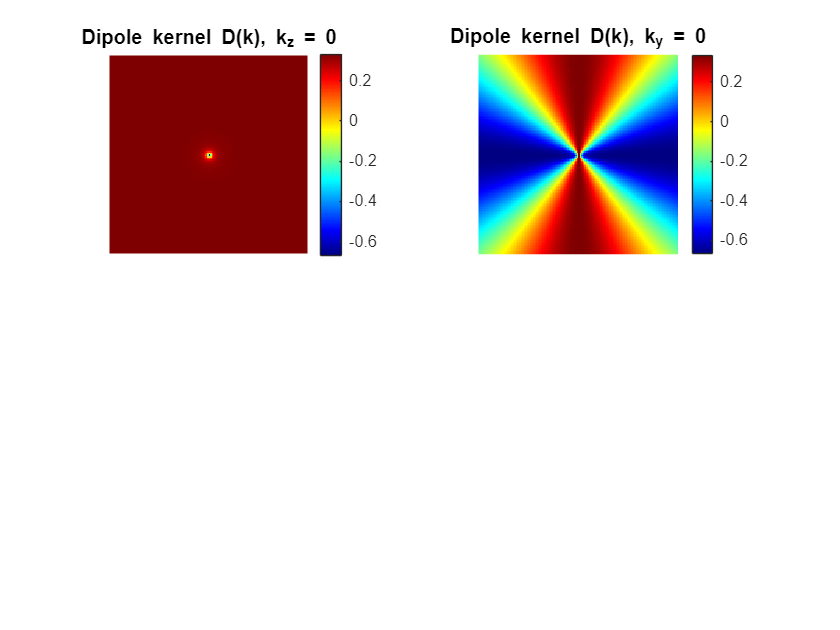


%% k-space grid
[kx, ky, kz] = ndgrid( ...
    (-N/2:N/2-1)/(N*voxel_size(1)), ...
    (-N/2:N/2-1)/(N*voxel_size(2)), ...
    (-N/2:N/2-1)/(N*voxel_size(3)) );

k2 = kx.^2 + ky.^2 + kz.^2;
k2(k2==0) = eps;   % avoid division by zero

%% Dipole kernel in k-space
Dk = 1/3 - (kz.^2 ./ k2);
%Dk = fftshift(Dk);

%% Display central slices
figure;
subplot(2,2,1)
imagesc(squeeze(Dk(:,:,N/2))), axis image off, colormap jet
colorbar
title('Dipole kernel D(k), k_z = 0')

subplot(2,2,2)
imagesc(squeeze(Dk(:,N/2,:))), axis image off, colormap jet
colorbar
title('Dipole kernel D(k), k_y = 0')

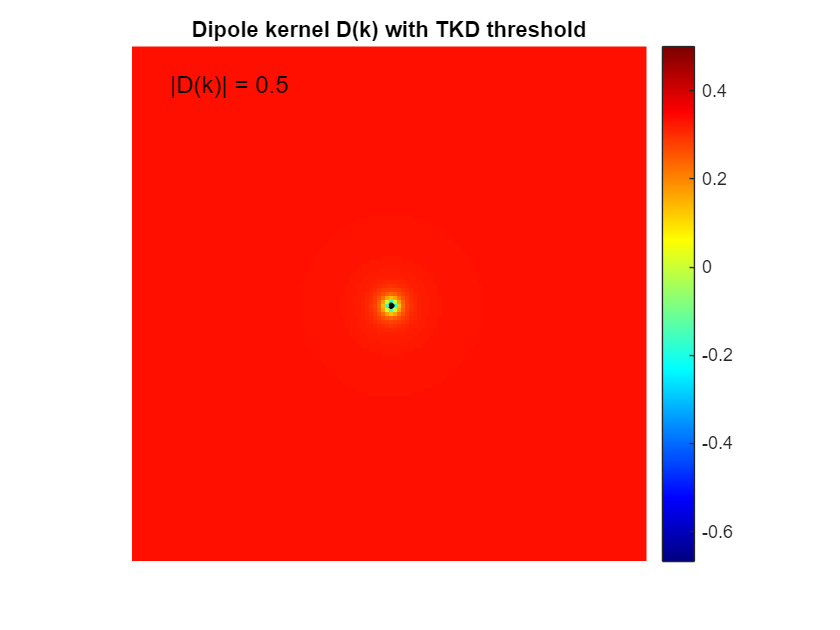

%% TKD inverse kernel
invDk_TKD = zeros(size(Dk));
mask = abs(Dk) >= thr;
invDk_TKD(mask) = 1 ./ Dk(mask);

figure;
imagesc(Dk(:,:,N/2)), axis image off
colormap jet
colorbar
title('Dipole kernel D(k) with TKD threshold')

hold on
contour(abs(Dk(:,:,N/2)), [thr thr], 'k', 'LineWidth', 2)
text(10,10,['|D(k)| = ' num2str(thr)], 'Color','k','FontSize',12)
hold off

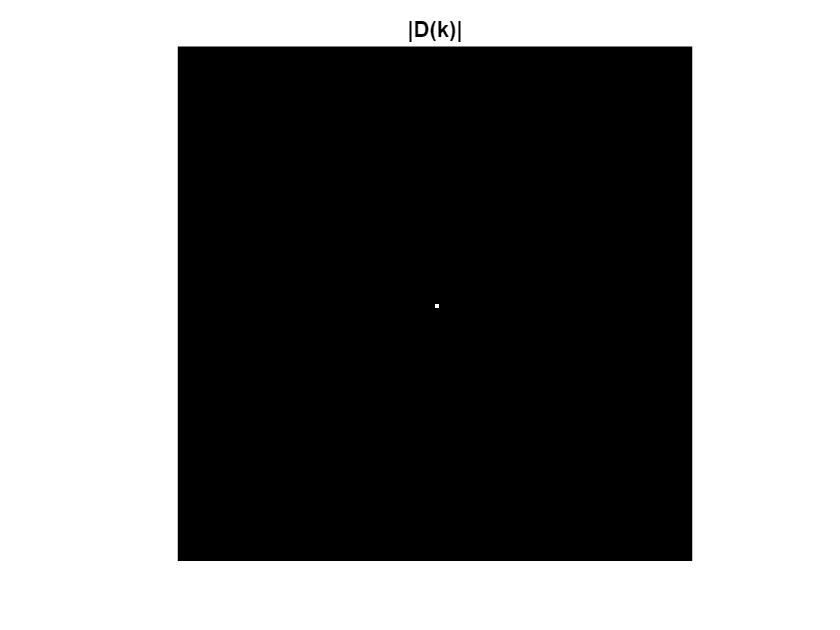


figure;
imagesc(mask(:,:,N/2)), axis image off
colormap gray
title('|D(k)|')

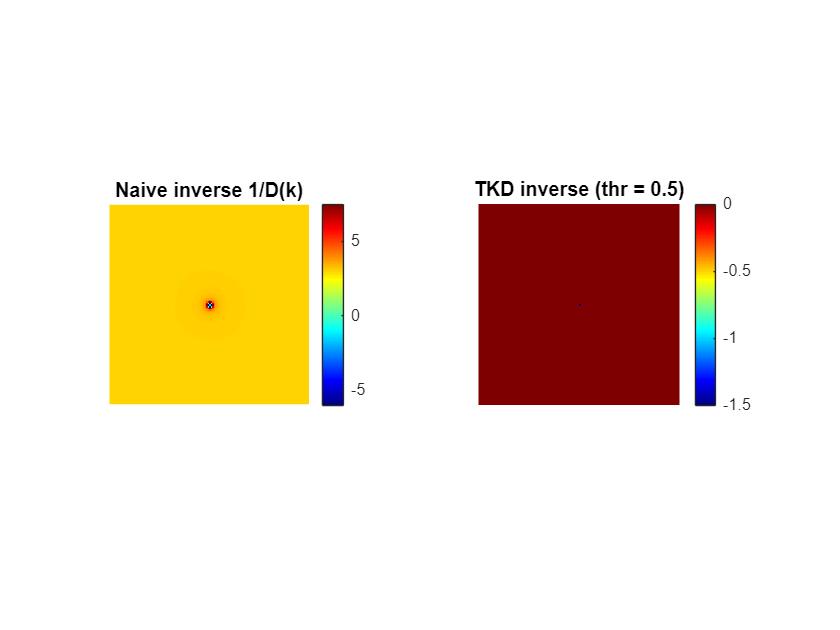

invDk_naive = 1 ./ Dk;
invDk_naive(~isfinite(invDk_naive)) = 0;

figure;
subplot(1,2,1)
imagesc(invDk_naive(:,:,N/2)), axis image off
colormap jet
colorbar
title('Naive inverse 1/D(k)')

subplot(1,2,2)
imagesc(invDk_TKD(:,:,N/2)), axis image off
colormap jet
colorbar
title(['TKD inverse (thr = ' num2str(thr) ')'])

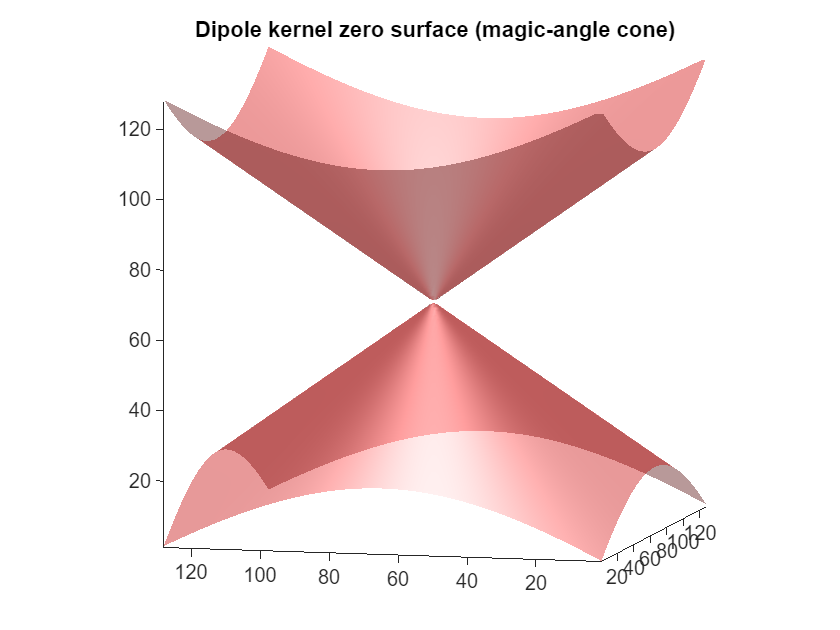

figure;
p = patch(isosurface(Dk, 0));   % D(k) = 0 surface
isonormals(Dk, p)

set(p, 'FaceColor', 'red', ...
       'EdgeColor', 'none', ...
       'FaceAlpha', 0.4)

axis equal tight
camlight headlight
lighting gouraud
view(3)

title('Dipole kernel zero surface (magic-angle cone)')

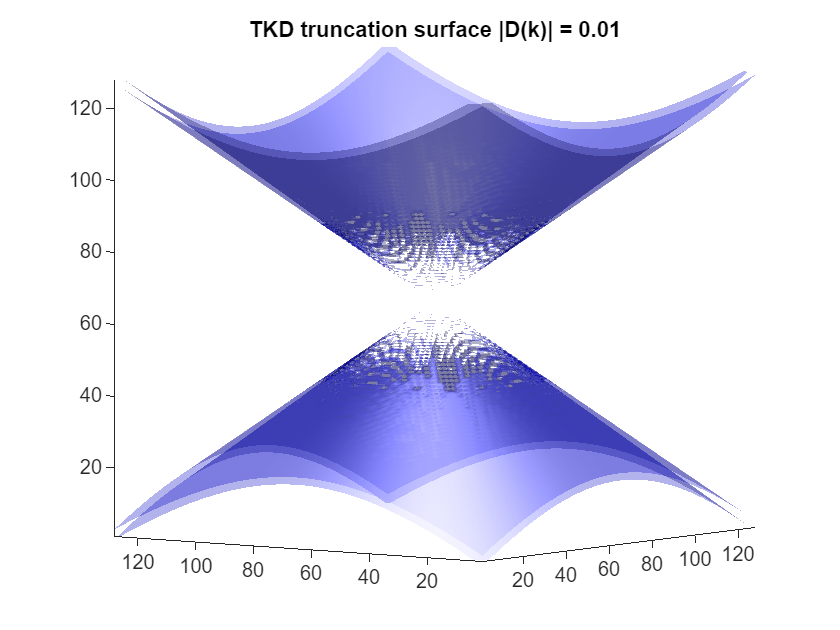

figure; hold on;

% +thr surface
p1 = patch(isosurface(abs(Dk), thr));
isonormals(abs(Dk), p1)
set(p1, 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.3)

% -thr surface (same abs-value)
p2 = patch(isosurface(abs(Dk), thr));
set(p2, 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.3)

axis equal tight
camlight headlight
lighting gouraud
view(3)

title(['TKD truncation surface |D(k)| = ' num2str(thr)])